# WEEK 5 PRACTICE QUIZ

Question 1

Below is a plot that shows the number of sunspots astronomers have observed on the sun from the years 1700 to 1987. You can see a series of prominent peaks in this data due to the cyclical nature of sunspots.

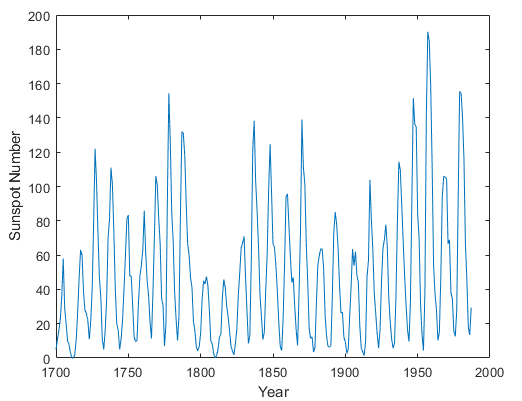

Load this data in MATLAB with the following code in a live script

`load sunspot.dat`

`yr = sunspot(:,``1``);`

`sunspotNumber = sunspot(:,``2``);`

Next, insert a "Find Local Extrema" Live Editor Task and use the variables **sunspotNumber** and **yr** as the "Input data"  and "X-axis" respectively. Use this Task to answer the following questions 

Which of the following values is closest to the prominence value of the largest peak in this graph? Remember that the prominence value is a measure of how much a peak stands out in the data, and you can identify peaks with higher prominence by changing the “Min. prominence” value.

- 2

- 20

- 200

- 2000

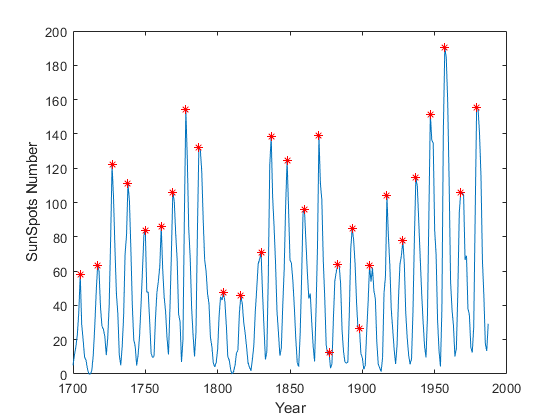

load sunspot.dat
yr = sunspot(:,1);
sunspotNumber = sunspot(:,2);
T = islocalmax(sunspotNumber,'MinSeparation',5);
plot(yr,sunspotNumber,yr(T),sunspotNumber(T),'r*')
xlabel("Year")
ylabel("SunSpots Number")

max(sunspotNumber);
disp("200")

200


Question 2

Which of the following values would be the best choice for the minimum separation if you only want to identify 1 peak per sunspot cycle?

- 0.5 years

- 5 years

- 50 years

- 500 years

disp("5")

5


Question 3

There is a distinct periodicity or cyclical nature to the data that leads to the series of peaks. What is the “fundamental period” of this a signal? In other words, what is the average number of years between the prominent peaks of this signal?

PeakPos = find(T==1);
disp(PeakPos(2)-PeakPos(1))

    12

